## Spectral Flatness Test

Explores tests for spectral flatness through simulation

% Validate and stress-test spectral flatness calculation used in chaos diagnostics.
% - Works with your existing compute_power_spectrum / compute_spectral_flatness.
% - If those are not on path, compatible local versions are defined at bottom.
% - Exercises pure tone, multi-tone, quasi-periodic, white/colored noise, and logistic-map signals.
% - Demonstrates band-limited SF and zero-power bin effects.

clear; clc; close all;

%% Parameters
fs      = 200;              % Hz
dt      = 1/fs;
T       = 60;               % seconds (long enough for stable spectra)
N       = round(T*fs);
t       = (0:N-1)*dt;

% Analysis band (match your diagnostics defaults if you like)
freq_min = 0.3;
freq_max = 10.0;

%% Construct test signals
f1 = 2.00;                   % Hz
f2 = 3.25;                   % Hz (incommensurate with f1 at given fs, quasi-periodic)
A1 = 1.0; A2 = 0.7;

x_tone         = A1*sin(2*pi*f1*t);
x_two_tone     = A1*sin(2*pi*f1*t) + A2*sin(2*pi*f2*t);
x_quasiperiod  = A1*sin(2*pi*sqrt(2)*t) + 0.6*sin(2*pi*sqrt(3)*t);  % irrationals for quasi
x_white        = randn(1,N);
x_colored      = filter([1 0.25 0.1], [1 -1.6 0.7], randn(1,N));    % crude colored noise

% Logistic map (chaos-like), then mean-remove & mild low-pass to confine band energy
r  = 4.0; x = 0.12345; x_log = zeros(1,N);
for n = 2:N, x = r*x*(1 - x); x_log(n) = x; end
x_log = x_log - mean(x_log);
[b,a] = butter(2, (freq_max/fs)*2*0.8);       % gentle LP toward analysis band
x_log_filt = filtfilt(b,a,x_log);

% Aggregate
signals = {x_tone, x_two_tone, x_quasiperiod, x_white, x_colored, x_log_filt};
names   = {'Pure tone','Two tones','Quasi-periodic','White noise','Colored noise','Logistic-map (LP)'};

%% Compute spectra and spectral flatness
all_SF_full = zeros(1,numel(signals));
all_SF_band = zeros(1,numel(signals));

spec = struct('f',[],'P',[]); spec = repmat(spec, 1, numel(signals));

for k = 1:numel(signals)
    x = signals{k};
    [f, P] = local_power_spectrum(x, dt);  % uses your function if present
    spec(k).f = f; spec(k).P = P;

    % Full-band SF
    SF_full = local_spectral_flatness(P);  % uses your function if present

    % Band-limited SF (your diagnostics style)
    mask = (f >= freq_min) & (f <= freq_max);
    P_band = P(mask);
    if nnz(mask) < 4
        SF_band = NaN;                      % insufficient resolution
    else
        SF_band = local_spectral_flatness(P_band);
    end

    all_SF_full(k) = SF_full;
    all_SF_band(k) = SF_band;
end

%% Display numeric results
fprintf('\nSpectral Flatness Results\n');


Spectral Flatness Results


fprintf('-------------------------------------------------------------\n');

-------------------------------------------------------------


fprintf('%-18s |  SF(full)   SF(%.1f–%.1f Hz)\n', 'Signal', freq_min, freq_max);

Signal             |  SF(full)   SF(0.3–10.0 Hz)


fprintf('-------------------------------------------------------------\n');

-------------------------------------------------------------


for k = 1:numel(signals)
    fprintf('%-18s |  %7.4f     %7.4f\n', names{k}, all_SF_full(k), all_SF_band(k));
end

Pure tone          |   0.0000      0.0000
Two tones          |   0.0000      0.0000
Quasi-periodic     |   0.0001      0.0012
White noise        |   0.5623      0.5684
Colored noise      |   0.0193      0.5313
Logistic-map (LP)  |   0.0005      0.4602


fprintf('-------------------------------------------------------------\n');

-------------------------------------------------------------


fprintf('Notes:\n');

Notes:


fprintf(' - Expect SF ~ 0 for a pure tone; ~1 for white noise.\n');

 - Expect SF ~ 0 for a pure tone; ~1 for white noise.


fprintf(' - Quasi-periodic and multi-tone should lie between 0 and ~0.4.\n');

 - Quasi-periodic and multi-tone should lie between 0 and ~0.4.


fprintf(' - Colored noise usually < white noise (due to spectral concentration).\n\n');

 - Colored noise usually < white noise (due to spectral concentration).



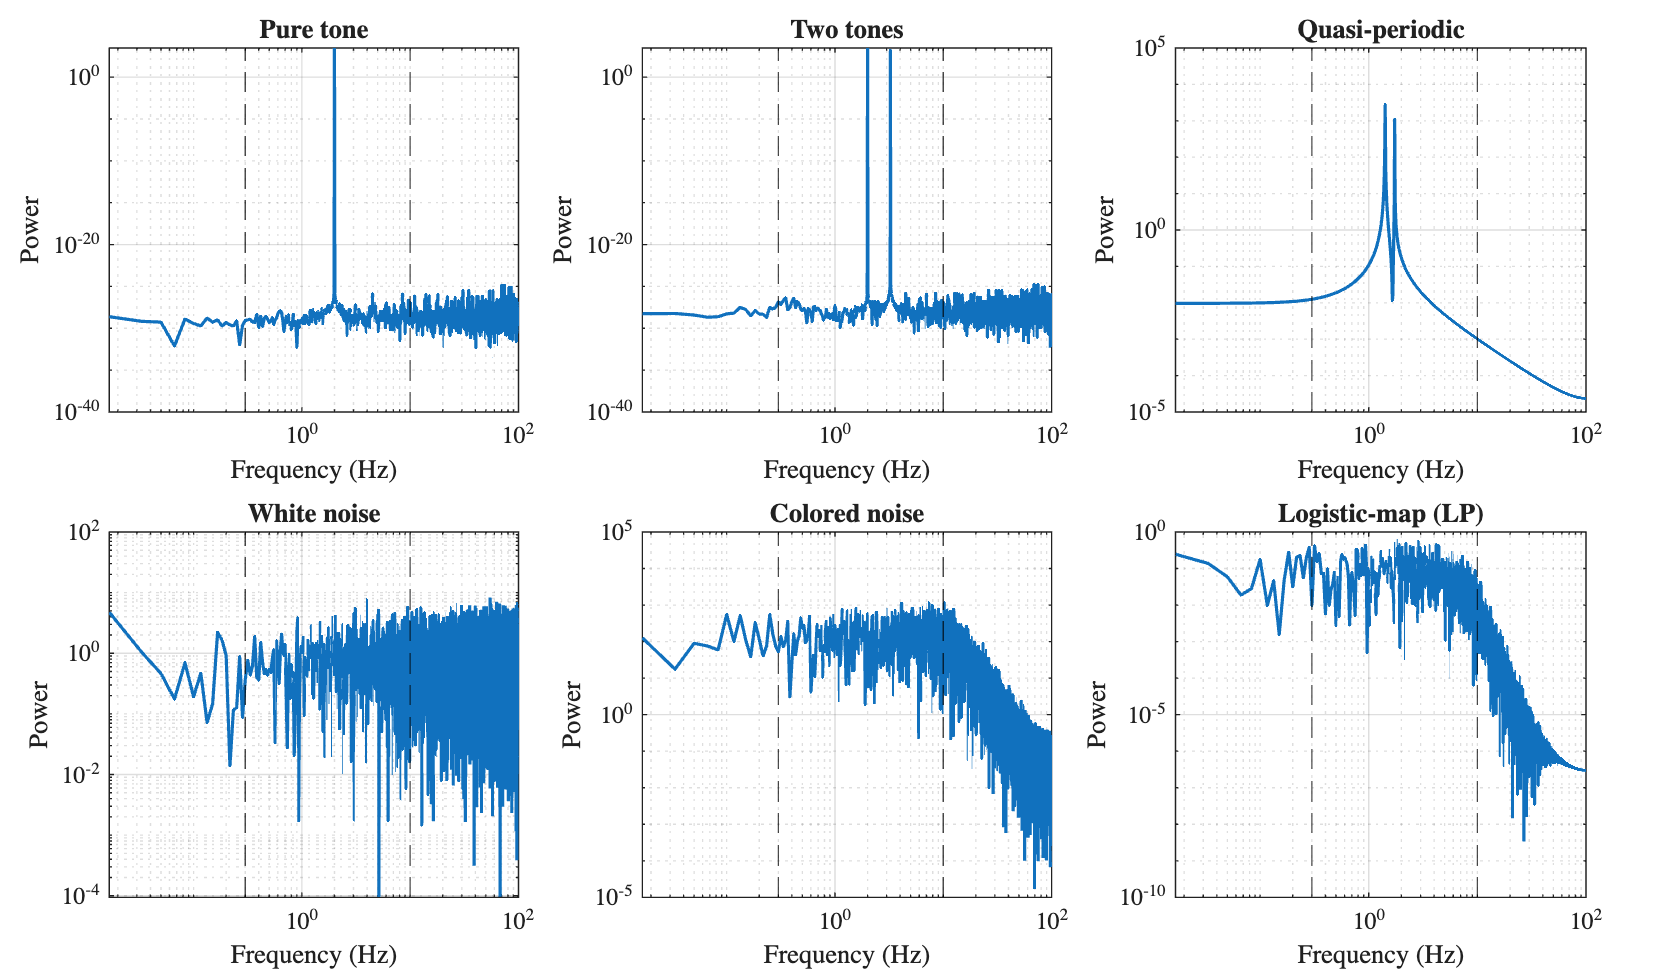


%% Visualization: spectra (log-log) and SF bars
figure('Name','Power Spectra (log-log)','Position',[80 80 1200 700]);
tiledlayout(2,3,'Padding','compact','TileSpacing','compact');
for k = 1:numel(signals)
    nexttile;
    f = spec(k).f; P = spec(k).P;
    loglog(f, P, 'LineWidth', 1.2); hold on;
    xline(freq_min,'k--'); xline(freq_max,'k--');
    grid on; xlabel('Frequency (Hz)'); ylabel('Power');
    title(sprintf('%s', names{k}));
    xlim([max(1e-3, f(2)) 0.5*fs]);
end

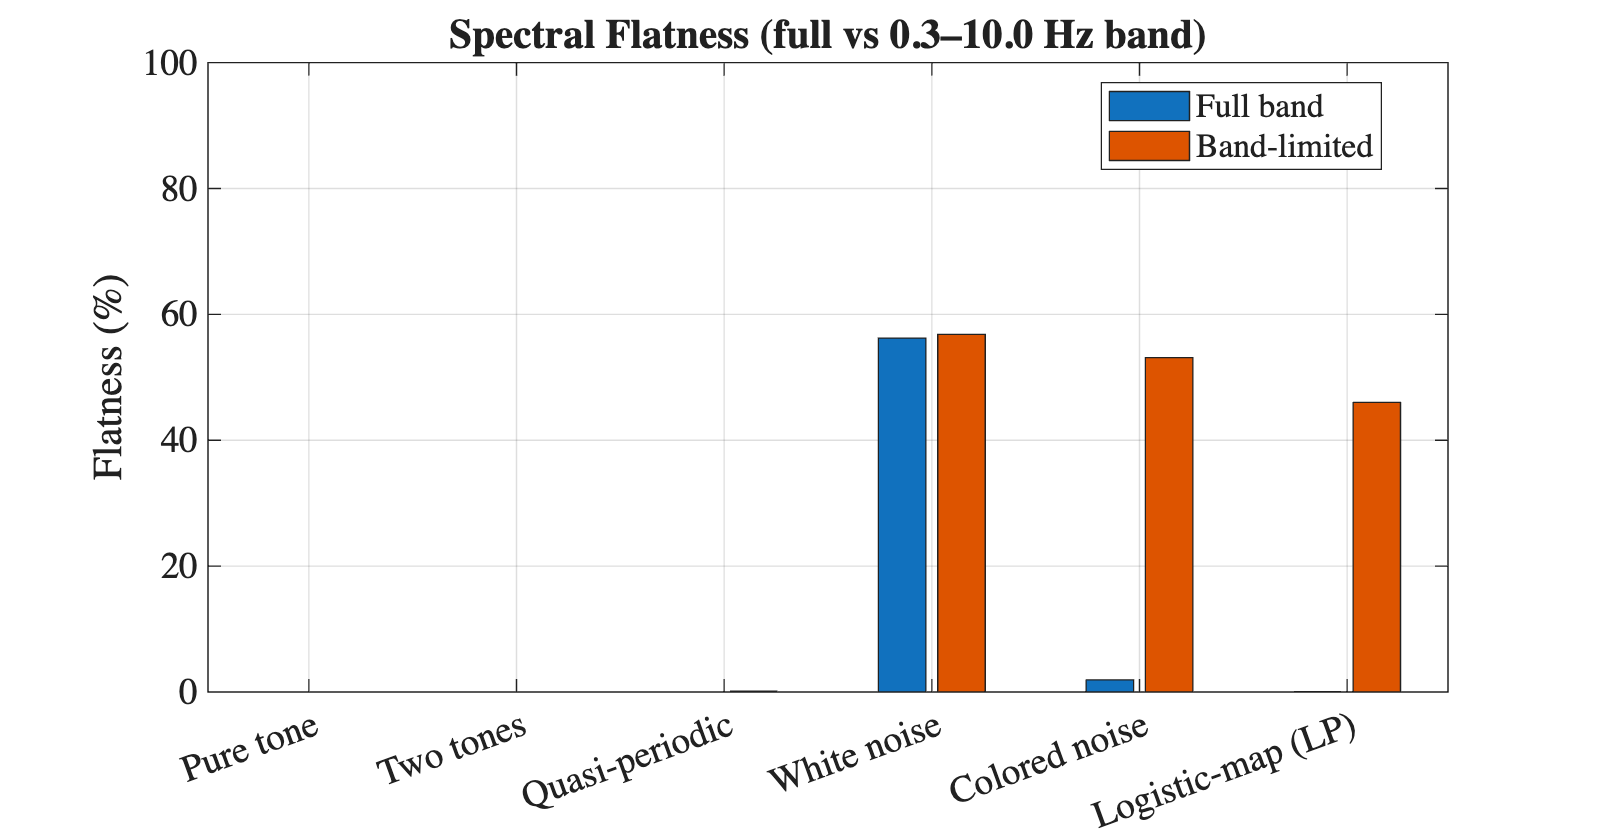


figure('Name','Spectral Flatness Summary','Position',[200 200 800 420]);
bar_data = [all_SF_full(:), all_SF_band(:)] * 100;
bar(bar_data,'grouped'); grid on;
xticklabels(names); ylabel('Flatness (%)'); ylim([0 100]);
legend({'Full band','Band-limited'},'Location','best');
title(sprintf('Spectral Flatness (full vs %.1f–%.1f Hz band)', freq_min, freq_max));
xtickangle(20);


%% Explicit zero-power bin test (diagnose effect of zeros)
% Construct artificial power vectors with exact zeros and compare SF with/without eps.
P_sparse = zeros(1,256);
P_sparse([10 50 120]) = [1 0.3 0.1];  % three spectral lines, zeros elsewhere

SF_no_guard = local_spectral_flatness_no_guard(P_sparse);     % geometric/arith without eps
SF_with_eps = local_spectral_flatness(P_sparse);               % your guarded version

fprintf('Zero-power bin stress test:\n');

Zero-power bin stress test:


fprintf('  SF without +eps guard (zeros present): %.6f (expected 0)\n', SF_no_guard);

  SF without +eps guard (zeros present): 0.000000 (expected 0)


fprintf('  SF with    +eps guard (zeros present): %.6f (>0 due to eps)\n', SF_with_eps);

  SF with    +eps guard (zeros present): 0.000000 (>0 due to eps)


fprintf('Recommendation: Keep the +eps guard or mask zero bins.\n\n');

Recommendation: Keep the +eps guard or mask zero bins.




% Optional: mask out exact-zeros as if they were outside the analysis band
mask_nz = P_sparse > 0;
SF_masked = local_spectral_flatness(P_sparse(mask_nz));
fprintf('  SF after masking zeros:                 %.6f (more representative of sparseness)\n\n', SF_masked);

  SF after masking zeros:                 0.665836 (more representative of sparseness)



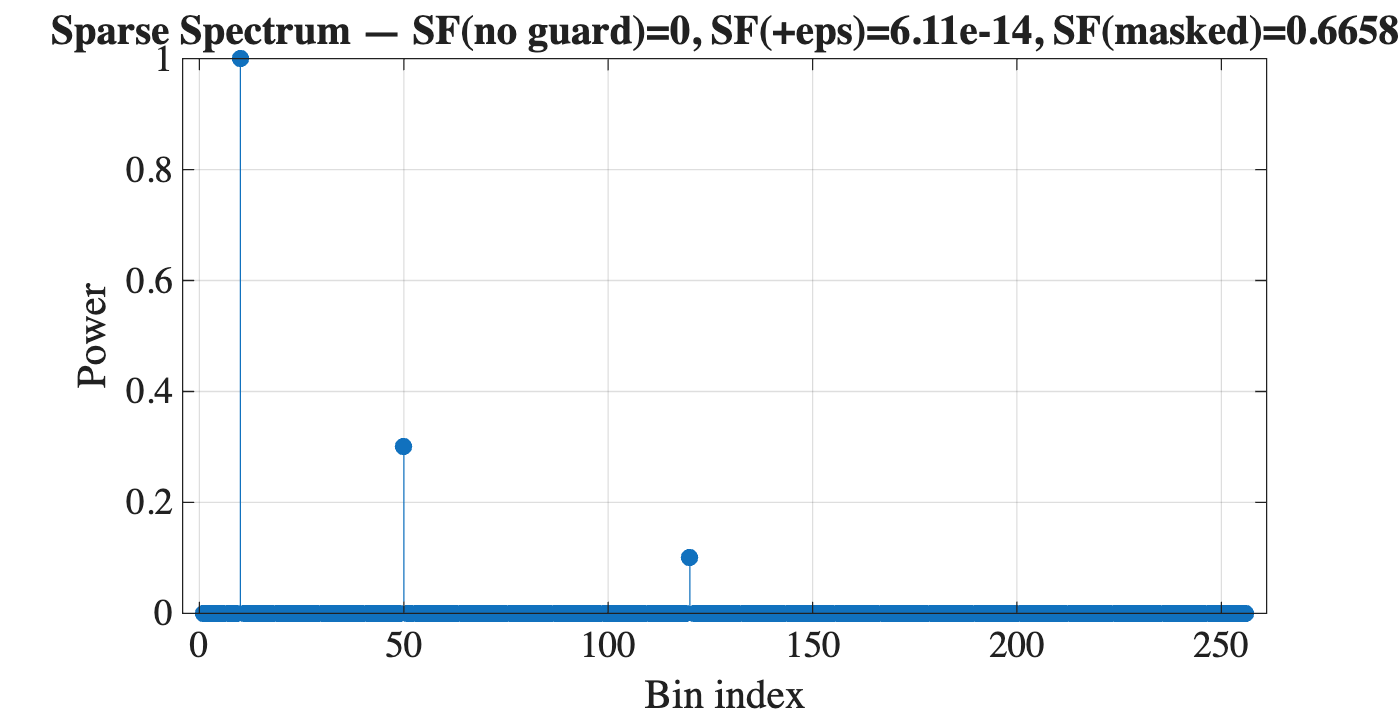


% Visualize the sparse spectrum
figure('Name','Zero-power Bin Effect','Position',[260 260 700 360]);
stem(P_sparse,'filled'); grid on; xlabel('Bin index'); ylabel('Power');
title(sprintf('Sparse Spectrum — SF(no guard)=%.4g, SF(+eps)=%.4g, SF(masked)=%.4g', ...
    SF_no_guard, SF_with_eps, SF_masked));


%% Helper wrappers that prefer your functions if available
function [f, P] = local_power_spectrum(x, dt)
    % Prefer user's compute_power_spectrum if it exists on path
    if exist('compute_power_spectrum','file') == 2
        [f, P] = compute_power_spectrum(x, dt);
        return;
    end
    % Compatible local fallback
    N = numel(x);
    X = fft(x - mean(x));
    P2 = abs(X).^2 / N;
    f2 = (0:N-1)/(N*dt);
    % One-sided
    lo = 1; hi = floor(N/2);
    f = f2(lo:hi);
    P = P2(lo:hi);
end

function SF = local_spectral_flatness(P)
    % Prefer user's compute_spectral_flatness if it exists on path
    if exist('compute_spectral_flatness','file') == 2
        SF = compute_spectral_flatness(P);
        return;
    end
    % Compatible local fallback with +eps guard (matches your implementation)
    gmeanP = exp(mean(log(P + eps)));
    ameanP = mean(P);
    SF = gmeanP / max(ameanP, eps);
end

function SF = local_spectral_flatness_no_guard(P)
    % Geometric/Arithmetic mean with NO +eps guard (for stress testing zeros)
    % If any P(k)==0, geometric mean => 0, so SF=0.
    P = P(:);
    if any(P < 0)
        error('Power vector contains negative values.');
    end
    % Handle degenerate all-zero case
    if all(P == 0)
        SF = 0;
        return;
    end
    gmeanP = exp(mean(log(P + (P==0)*0)));  % exact zeros => log(0) = -Inf => exp(mean) = 0
    ameanP = mean(P);
    SF = gmeanP / ameanP;
end
